## МИУ 

MFIE - граничное условие для магнитного опля

#### H - поляризация

Сравнение нашего метода для MFIE с классическим MAS.

Сравнение проводиться с помощью вычитания токов 1го метода из токов другог и потом взятия по модулю.

16-02-21

close all;
clear variables;

## 1. Тестирование - предварительное

Сравним полученные данные, с данными расчитаными вручную. 

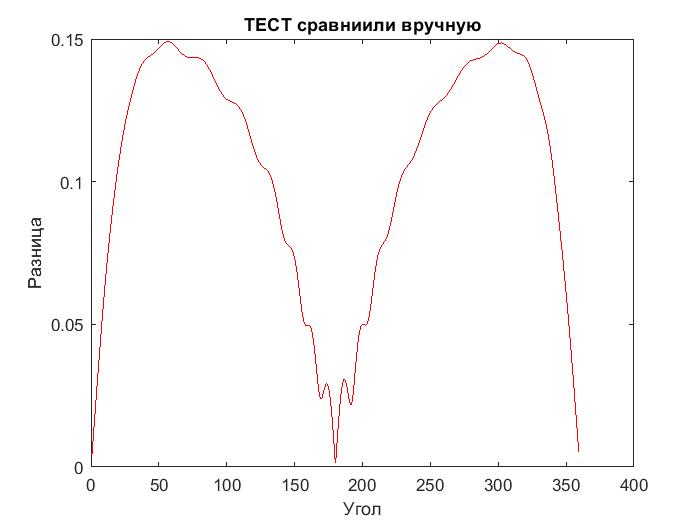

% MIE MFIE H_pol
% Параметры N=400, a=1, b =1, phi = 0
I_comp_test = load("MFIE_MAS_H_pol_400", "I").I;
phi_graph_test = load("MFIE_MAS_H_pol_400", "phi_for_graf_real").phi_for_graf_real;

% MAS H_pol
% Параметры N_mas = 400, N_ref = 400, a=1, b =1, phi = 0
I_ref_test = load("MAS_H_pol_400", "I_real").I_real;

% вычтем и возьмем модуль
de_I_test = abs(I_ref_test + I_comp_test);

% постриом график теста 
figure; 
plot(phi_graph_test, de_I_test,'r-');
title('ТЕСТ cравниили вручную'); 
xlabel('Угол'); 
ylabel('Разница');

## 2. Главная часть скрипта

Задаем параметры эллипса и падающей волны 

a = 2; 
b = 1;
phi_grad = 60; 

Предположим мы получили невязку $10^{-14}$ для МВИ источников и выбрали количество источник N_mas_ref

N_mas_ref = 400;

Выбираем количество участков разибения N_comp для МИУ для 1-го графика

N_comp = 1200;

Генерируем N_comp точки на элипсе X_comp, Z_comp.

% Сгенерируем параметры элипса и упакуем их в структуру
S = generate_elips_point(a,b,N_comp);

% параметры a,b и угол падения волны запишем в стр-ру - чтоб собой не таскать
S.phi_grad = phi_grad;
S.a = a;
S.b = b;

Для этих точек (X_comp, Z_comp) в количества N_comp шт. считаем МВИ и получем токи I_ref (длиной N_comp)

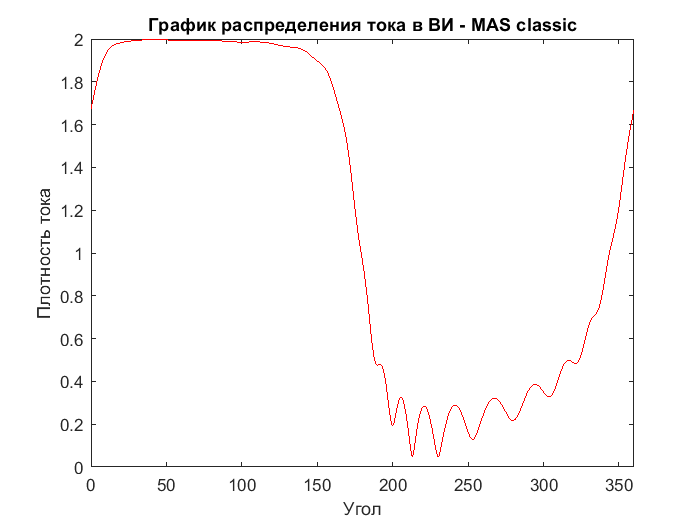

I_ref = MAS_elips_clasic(N_mas_ref, N_comp, S);

Для этих точек (X_comp, Z_comp) в количества N_comp шт. считаем МИУ и получем токи I_comp (длиной N_comp)

Напомним что количество источников N_mas_ref, а количество точек на основном элипсе N_сomp

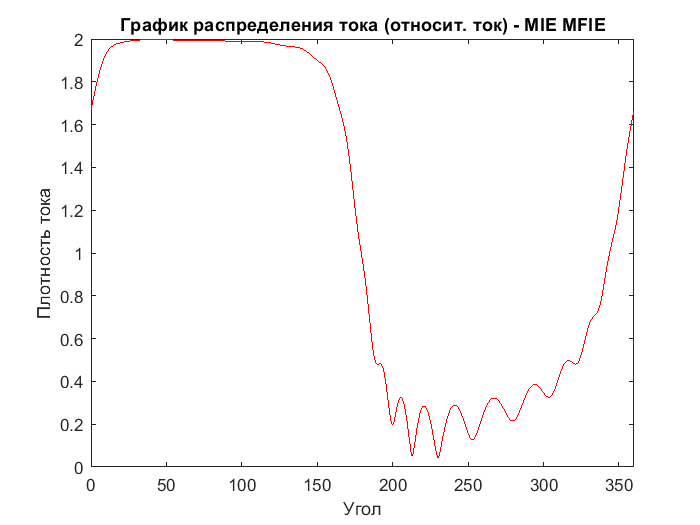

I_comp = MFIE_MIE_H_pol_elips(N_comp, S);

Сравниваем токи и записываем в график 

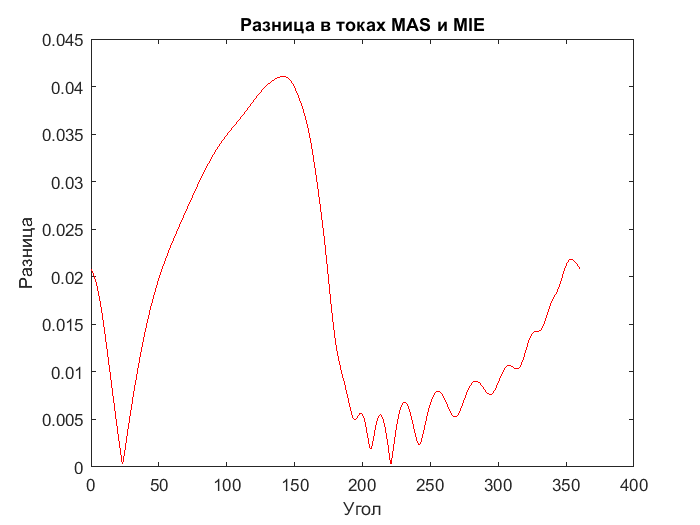

% разность токов
de_I = abs(I_ref - I_comp);

% распакуем рельные углы для графика из струкутры
phi_for_graf_real = S.phi_for_graf_real;

% построим график абсолютной разности токов
figure; 
plot(phi_for_graf_real, de_I,'r-');
title('Разница в токах MAS и MIE'); 
xlabel('Угол'); 
ylabel('Разница');

Запишем разницу токов в файл 

% name_file = strcat('MFIE_MIE_Hpol_compare_elips_',  num2str(N_comp), '.dat'); % в имея файла добавил число отрезков автоматом 
% 
% f01 = fopen(name_file,'w');
% for n=1:N_comp
%     fprintf(f01,' %10.5f %10.5f\n', phi_for_graf_real(n), de_I(n));
% end
% fclose(f01);

Посчитаем ЭПР МИУ MFIE

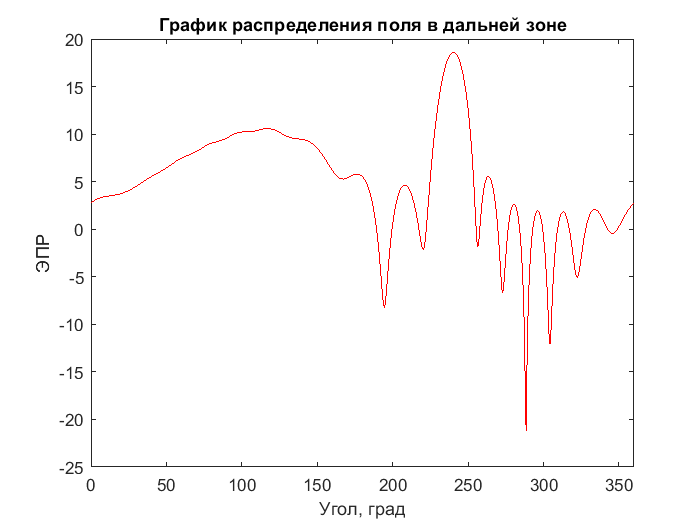

Sum_H_comp = DA_MFIE_MIE_H_pol_elips(N_comp, I_comp, S);

Посчитаем ЭПР MAS 

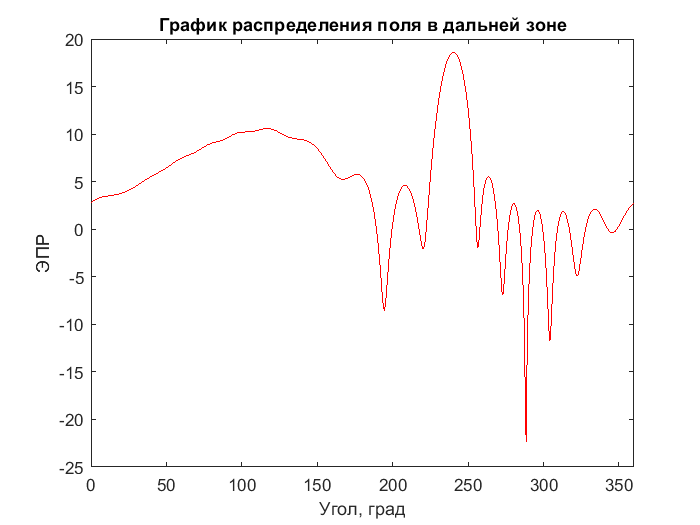

Sum_H_ref = DA_MAS_H_pol_elips(N_mas_ref, N_comp, I_ref, S);

Сравниваем ЭПР и записываем в график 

% разность cуммарных полей
de_Sum_H = Sum_H_ref - Sum_H_comp;

% расчет ЭПР
de_DA = zeros(length(de_Sum_H));
for i = 1 : length(de_Sum_H)
    de_DA(i) = 10*log10((2/pi)*de_Sum_H(i)*conj(de_Sum_H(i)));
end

% генератор углов для построения графика
phi_for_graf_DA = zeros(721,1);
for p = 1 : 721
    phi_for_graf_DA(p) = (p-1)/2;
end  
% построим график абсолютной разности ЭПР в дб
figure; 
plot(phi_for_graf_DA, de_DA,'r-');

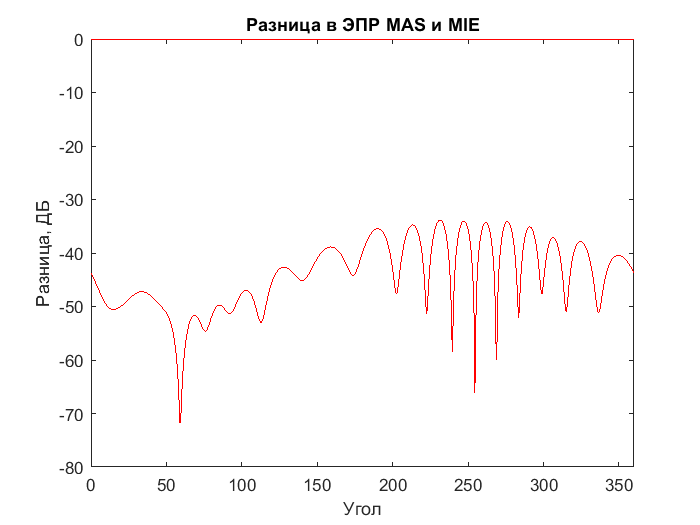

title('Разница в ЭПР MAS и MIE'); 
xlabel('Угол'); 
xlim([0 360])
ylabel('Разница, ДБ');

Запишем разницу ЭПР в файл 

name_file = strcat("DA_MFIE_MIE_Hpol_compare_elips_", num2str(N_comp), '.dat'); % в имея файла добавил число отрезков автоматом 

f02 = fopen(name_file,'w');
for n=1:length(de_DA)
    fprintf(f02,' %10.5f %10.5f\n', phi_for_graf_DA(n), de_DA(n));
end
fclose(f02);

## 3. Описание функций которые вызываются выше

### 1. Структура для генерации точек элипса 

function[S] = generate_elips_point(a,b,N)

Входные параметры

    delta_phi = 360/N;

Генерация точек

    delta_phi = 360/N;
    x = zeros(1,N);
    z = zeros(1,N);
    
    for i = 1 : N
        z(i) = b*sind(delta_phi*(i-1));
        x(i) = a*cosd(delta_phi*(i-1));
    end
    

Расчет dx для каждого участка

    for i = 1 : N
        if i == N
            d_x = (x(1)-x(i));
            d_z = (z(1)-z(i));
        else
            d_x = (x(i+1)-x(i));
            d_z = (z(i+1)-z(i));
        end
        
        dx(i) = sqrt(d_x^2+d_z^2);    
    end

Посчитаем t для каждого отрезка

    for i = 1 : N
        if i == N
            tx(i) = -((x(1)-x(i)))/dx(i);
            tz(i) = -((z(1)-z(i)))/dx(i);
        else
            tx(i) = -(x(i+1)-x(i))/dx(i);
            tz(i) = -(z(i+1)-z(i))/dx(i);
        end
    end

Посчитаем n для каждого отрезка

    %   нормальный вектор найдем с помощью матрицы повороты
        alpha = -90;
        matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];
    
    for i = 1 : N
         matrix_temp = [tx(i), tz(i)]*matrix;
         nx(i) = matrix_temp(1);
         nz(i) = matrix_temp(2);
    end

Координаты центров отрезков

    for i = 1 : N 
        if i == N
            x_midle(i) = ((x(1)+x(i)))/2;
            z_midle(i) = ((z(1)+z(i)))/2;
        else
            x_midle(i) = (x(i+1)+x(i))/2;
            z_midle(i) = (z(i+1)+z(i))/2;
        end    
    end
        

Сделаем счетчик для графика в градусах

    for i = 1 : N
        z_m = z_midle(i);
        x_m = x_midle(i);
        
        if (x_m <= 0 && z_m < 0) || (x_m >= 0 && z_m < 0)
            phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi+360;
        else
            phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi;
        end
    end

%   упакуем это в струкутру 
    S = struct();
    % параметры эллипса 
    S.x = x;
    S.z = z;
    S.dx = dx;
    S.x_midle = x_midle;
    S.z_midle = z_midle;
    S.tx = tx;
    S.tz = tz;
    S.nx = nx;
    S.nz = nz;
    % входные параметры
    S.phi_for_graf_real = phi_for_graf_real;
    
end


### 2. MIE MFIE

function[I] = MFIE_MIE_H_pol_elips(N_comp, S)

Входные параметры

    
    N = N_comp;
    delta_phi = 360/N;
    k = 2*pi; 
    
    % распакуем структуру
    % параметры эллипса 
    dx = S.dx;
    tx = S.tx;
    tz = S.tz;
    nx = S.nx;
    nz = S.nz;
    x_midle = S.x_midle;
    z_midle = S.z_midle;
    % параметры падающей волны 
    phi_grad = S.phi_grad;

Порог

    treshold = 1*max(dx);

Дополнительные параметры

    gamma = 1.781072417990;
    delta = dx/2;

Изучим один цикл    

    for m = 1 : N
        
    %   Координаты в исходной системе координат (в ГСК) 
    % - т.к. точки находятся в центре отрезков разбиения
        xm = x_midle(m);
        zm = z_midle(m);
        txm = tx(m);
        tzm = tz(m);
        nxm = nx(m);
        nzm = nz(m);
        
        for n = 1 : N
        %   Координаты в исходной системе координат (в ГСК)
            xn = x_midle(n);
            zn = z_midle(n);
            txn = tx(n);
            tzn = tz(n);
            nxn = nx(n);
            nzn = nz(n);
    
        %   Центр новой системы кооридны - начало отрезка (в ГСК)

Давай возьмем середину отрезка

            x_begin_O2 = xn;
            z_begin_O2 = zn;
            
        %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
            x_mO2 = xm - x_begin_O2;
            z_mO2 =  zm - z_begin_O2;
             
    %       Положим этот вектор на новую СК
    %       Координаты этой точки (в ЛСК)
            xmO2 = x_mO2*txn + z_mO2*tzn;
            zmO2 = x_mO2*nxn + z_mO2*nzn;
               

Т.к. взяли на начало середину отрезка то тут будет

            % координаты в локальных координатах
            umn = xmO2;
            wmn = zmO2;
    
    %       Растояние между m и n (в ГСК)
            xmn = xm - xn;
            zmn = zm - zn;
            r = sqrt(xmn^2 + zmn^2);
            
    %       Расчет матричных элементов (в ЛСК)
            
            Hys = 0;
         
            cur_dx = dx(n); % current dx
            
            if n == m %r < 0.001*dx 
                
                % y - cоставляющая 
                Hys = -0.5;
                
            elseif abs(n - m) < 1.5 %r <= 2*dx
                % y - cоставляющая                     
                umn_plus_dx2 = umn + cur_dx/2;
                umn_minus_dx2 = umn - cur_dx/2;
                Hys = -(1i/8*wmn*k^2*cur_dx + 1/(2*pi)*(atan(umn_plus_dx2/wmn) - atan(umn_minus_dx2/wmn)));
                     
            else 
                % y - cоставляющая
                rmn = sqrt(umn^2 + wmn^2);    
                Hys = -1i/4*k*cur_dx*(wmn/rmn*besselh(1,1,k*rmn));  
                
            end
            
    %       символ кронкера
            if m == n
                kronker = 1;
            else 
                kronker = 0;
            end
            
            % расчет матричнх элементов 
            Zmn(m,n) = kronker + Hys;
        end
    end
     

Расчет падающего поля

    for m=1:N
        nxm = nx(m);
        nzm = nz(m);
        
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        
        % Определим координаты
        xm = x_midle(m);
        zm = z_midle(m);
        
    %   Итоговое падающее поле
        Hi(m,1) = exp(cx*xm+cz*zm); 
    end

Посчитаем токи и построим график

    % расчеток токов ВИ 
    I=Zmn\Hi;

Сделаем счетчик для графика в градусах

    % распакуем структуру 
    phi_for_graf_real = S.phi_for_graf_real;
    
    figure;
    fig = plot(phi_for_graf_real, abs(I), 'r');
    title('График распределения тока (относит. ток) - MIE MFIE'); 
    xlabel('Угол'); 
    xlim([0 360])
    ylabel('Плотность тока');

end



### 3. MAS CLASSIC

function[I_real] = MAS_elips_clasic(N_mas_ref, N_comp, S)

Входные параметры

    % распакуем структуру 
    % параметры эллипса
    a = S.a;
    b = S.b;
    
    % параметры падающей волны 
    phi_grad = S.phi_grad;
    delta_phi = 360/N_mas_ref;
    k = 2*pi; 
    
    % параметры внутренего элипса
    f = sqrt(a^2 - b^2);
    a1 = 1.8;  
    b1 = sqrt(a1^2 - f^2); 



Генерация точек элипса

    % распакуем структуру
    % параметры эллипса
    x = S.x;
    z = S.z;
        

Генерация точек контура для ВИ

    for i = 1 : N_mas_ref
        xAS(i) = a1*cosd(delta_phi*(i-1));
        zAS(i) = b1*sind(delta_phi*(i-1));
    end


Касательная к основному элипсу

    % распакуем структуру 
    % параметры эллипса
    dx = S.dx;
    tx = S.tx;
    tz = S.tz;
    nx = S.nx;
    nz = S.nz;

Изучим один цикл

    % count = 0;
    % пробегаемся по всем точкам оснвого элипса
    for m = 1 : N_comp
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
        %пробегаемся по всем точкам ВИ
        for n = 1 : N_mas_ref
            xn = xAS(n);
            zn = zAS(n);
            
            % Растояние между m и n
            dx = xm - xn;
            dz = zm - zn;
            r = sqrt(dx^2 + dz^2);
    
            Es(m,n) = besselh(1,1,k*r)*(dx*tzm - dz*txm)/r;         
            
        end
    end
     

Расчет падающего поля

    for m=1:N_comp
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        % Определим координаты
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
    %   Итоговое падающее поел - это суперпозиция полей
        Eix = +1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
        Eiz = -1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
        Ei(m,1) = Eix*txm + Eiz*tzm;         
    end
    

Посчитаем токи и построим график

    % расчеток токов ВИ 
    I=Es\Ei;
    
    for m = 1 : N_comp
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
        %пробегаемся по всем точкам ВИ
        sum_count = 0;
        for n = 1 : N_mas_ref
            xn = xAS(n);
            zn = zAS(n);    
        
            % Растояние между m и n
            xmn = (xm - xn);
            zmn = (zm - zn);
            r = sqrt(xmn^2 + zmn^2);
            
            Hs = I(n)*besselh(0, 1, k*r);
           
            sum_count = sum_count + Hs;
        end
        
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        Hi = exp(cx*xm+cz*zm); 
       
        I_real(m,1) = sum_count + Hi;
    end

Сделаем счетчик для графика в градусах

    % распакуем структуру 
    phi_for_graf_real = S.phi_for_graf_real;
 
    figure;
    fig = plot(phi_for_graf_real, abs(I_real), 'r');
    title('График распределения тока в ВИ - MAS classic'); 
    xlabel('Угол'); 
    xlim([0 360])
    ylabel('Плотность тока'); 
end


### 4. MIE MFIE ЭПР 

function[Sum_H_comp] = DA_MFIE_MIE_H_pol_elips(N_comp, I_comp, S)
    % Расчиитанные токи до этого и количество точек 
    I = I_comp; % чтоб не переписывать старую прогу 
    N = N_comp; % чтоб не переписывать старую прогу
    
    k = 2*pi; 
    
    % распакуем структуру
    % параметры эллипса 
    dx = S.dx;
    tx = S.tx;
    tz = S.tz;
    x_midle = S.x_midle;
    z_midle = S.z_midle;
    % параметры падающей волны 

    for p = 1 : 721
        Sum_H = 0;
        phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
        phi_for_graf_DA(p) = (p-1)/2; % угол для графика
        
        cx = - 1i*k*cosd(phi);
        cz = - 1i*k*sind(phi);
    
        for n = 1 : N
           txn = tx(n);
           tzn = tz(n);
           xn = x_midle(n);
           zn = z_midle(n);
           
           Sum_H = Sum_H + 1/4*I(n)*k*dx(n)*(txn*sind(phi) - tzn*cosd(phi))*exp(cx*xn+cz*zn);
        end
        
        Sum_H_mass(p) = Sum_H;
        RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));
    
    end
    
    % график поля в дальней зоне от угла налюденя (не нормированный)
    figure;
    plot(phi_for_graf_DA ,RCS,'r-');
    title('График распределения поля в дальней зоне'); 
    xlim([0 360])
    xlabel('Угол, град'); 
    ylabel('ЭПР');
    
    % массив который будет выводить
    Sum_H_comp = Sum_H_mass;    
end

### 5. ЭПР MAS classic

function[Sum_H_ref] = DA_MAS_H_pol_elips(N_mas_ref, N_comp, I_ref, S)
    % Расчиитанные токи до этого и количество точек 
    I = I_ref; % чтоб не переписывать старую прогу  
    N = N_comp; % чтоб не переписывать старую прогу 

Входные параметры

    % распакуем структуру 
    % параметры эллипса
    a = S.a;
    b = S.b;
    
    % параметры падающей волны 
    phi_grad = S.phi_grad;
    delta_phi = 360/N_mas_ref;
    k = 2*pi; 
    
    % параметры внутренего элипса
    f = sqrt(a^2 - b^2);
    a1 = 1.8;  
    b1 = sqrt(a1^2 - f^2); 



Генерация точек элипса

    % распакуем структуру
    % параметры эллипса
    x = S.x;
    z = S.z;
        

Генерация точек контура для ВИ

    for i = 1 : N_mas_ref
        xAS(i) = a1*cosd(delta_phi*(i-1));
        zAS(i) = b1*sind(delta_phi*(i-1));
    end


Касательная к основному элипсу

    % распакуем структуру 
    % параметры эллипса
    dx = S.dx;
    tx = S.tx;
    tz = S.tz;
    nx = S.nx;
    nz = S.nz;

Изучим один цикл

    % count = 0;
    % пробегаемся по всем точкам оснвого элипса
    for m = 1 : N_comp
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
        %пробегаемся по всем точкам ВИ
        for n = 1 : N_mas_ref
            xn = xAS(n);
            zn = zAS(n);
            
            % Растояние между m и n
            dx = xm - xn;
            dz = zm - zn;
            r = sqrt(dx^2 + dz^2);
    
            Es(m,n) = besselh(1,1,k*r)*(dx*tzm - dz*txm)/r;         
            
        end
    end
     

Расчет падающего поля

    for m=1:N_comp
        cx = -1i*k*cosd(phi_grad);
        cz = -1i*k*sind(phi_grad);
        % Определим координаты
        xm = x(m);
        zm = z(m);
        txm = tx(m);
        tzm = tz(m);
        
    %   Итоговое падающее поел - это суперпозиция полей
        Eix = +1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
        Eiz = -1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
        Ei(m,1) = Eix*txm + Eiz*tzm;         
    end
    

Посчитаем токи и построим график

    % расчеток токов ВИ 
    I=Es\Ei;  

ЭПР

    for p = 1 : 721
        Sum_H = 0;
        phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
        phi_for_graf_DA(p) = (p-1)/2; % угол для графика
        
        cx = - 1i*k*cosd(phi);
        cz = - 1i*k*sind(phi);
    
        for n = 1 : N_mas_ref
           Sum_H = Sum_H + I(n)*exp(cx*xAS(n)+cz*zAS(n)); 
        end
        
        Sum_H_mass(p) = Sum_H;
        RCS(p) = 10*log10((2/pi)*Sum_H*conj(Sum_H));
    
    end
    
    % график поля в дальней зоне от угла налюденя (не нормированный)
    figure;
    plot(phi_for_graf_DA ,RCS,'r-');
    title('График распределения поля в дальней зоне'); 
    xlim([0 360])
    xlabel('Угол, град'); 
    ylabel('ЭПР');
    
    Sum_H_ref = Sum_H_mass;
end